## Deliverable 6

This is an alternative implementation of the assignment using MATLAB libraries. The plots and results shown on the MATLAB console are there for the purpose of comparing with the deliverables of the main implementation. They were not submitted as .png files because it was not requested.

***See discussion at the ****end of the script*******

### Ridge Regression

% parameters
N = 400;
p = 9;
steps = 10e5;
alpha = 10e-6;

% Load dataset
df = readtable('Credit_N400_p9.csv');

% Binary encoding data frame's categorical variables
df.Gender = double(categorical(df.Gender));
df.Married = double(categorical(df.Married));
df.Student = double(categorical(df.Student));

y = df{:, 10};
X = df{:, 1:9};
lambda_values = [10^-2, 10^-1, 10^0, 10^1, 10^2, 10^3, 10^4];

% Standardized data
X = zscore(X);
y = y - mean(y);

% Ridge regression
B = ridge(y, X, lambda_values);

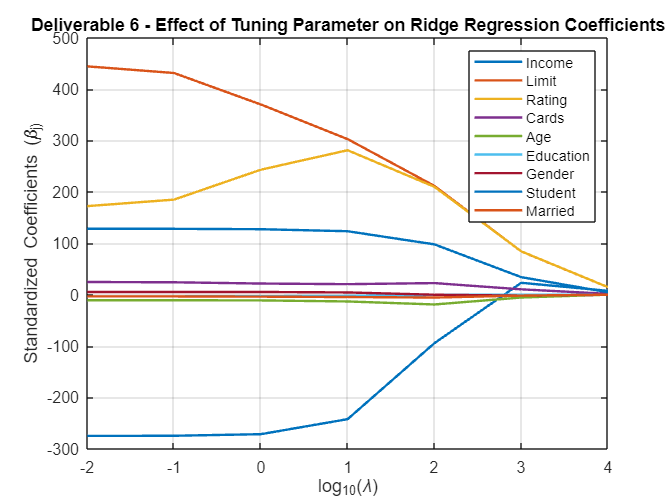

% Plot
line_styles = {'-', '--', ':', '-.', '-', '--', ':', '-.', '-'};
colors = lines(9);
feature_names = df(1, 1:9).Properties.VariableNames;
figure;
plot(log10(lambda_values), B, 'LineWidth', 1.5);
xlabel('log_{10}(\lambda)');
ylabel('Standardized Coefficients (\beta_j)');
title('Deliverable 6 - Effect of Tuning Parameter on Ridge Regression Coefficients');
legend(feature_names, 'Location','northeast');
grid on;

### Five-Fold Cross-Validation

% Partition in 5 folds
cv = cvpartition(length(X), "kfold", 5);

cvErrors = zeros(size(lambda_values));

for i = 1:length(lambda_values)
    lambda = lambda_values(i);
    
    % Fold Errors
    foldErrors = zeros(1, k);
    
    for j = 1:k
        % Split
        X_train = X(cv.training(j), :);
        y_train = y(cv.training(j));
        X_valid = X(cv.test(j), :);
        y_valid = y(cv.test(j));

        % Standardize
        y_center = mean(y_train);
        X_center = mean(X_train);
        X_std = std(X_train);

        X_train = (X_train - X_center) ./ X_std;
        X_valid = (X_valid - X_center) ./ X_std;

        % Train the ridge regression model
        B = ridge(y_train, X_train, lambda);

        % Make predictions on the validation set
        y_pred = X_valid * B;

        % Compute the mean squared error for this fold
        foldErrors(j) = mean((y_pred - y_valid).^2);
    end

    % Compute the mean error across all folds for this lambda
    cvErrors(i) = mean(foldErrors);
end

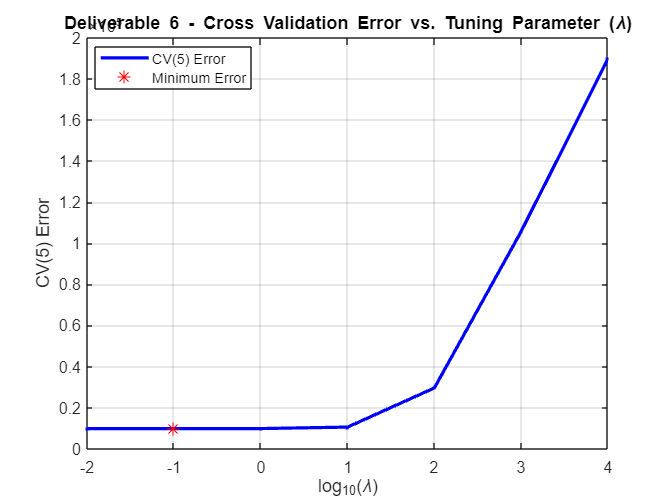

% Plot of CV(5) error vs. log-scaled lambda
log_lambda_values = log10(lambda_values);
figure;
plot(log_lambda_values, cvErrors, 'b.-', 'LineWidth', 2);
xlabel('log_{10}(\lambda)');
ylabel('CV(5) Error');
title('Deliverable 6 - Cross Validation Error vs. Tuning Parameter (\lambda)');
grid on;

% Minimum CV(5) error pmarked w red circle
[~, min_error_idx] = min(cvErrors);
hold on;
plot(log_lambda_values(min_error_idx), cvErrors(min_error_idx), 'r*', 'MarkerSize', 8);

% Legend
legend('CV(5) Error', 'Minimum Error', 'Location', 'Best');

### Retrain with Optimal Parameter

bestLambda = lambda_values(min_error_idx);
fprintf('Deliverable 6 - The value of 𝜆 that generated the smallest CV(5) error is %.4f\n', bestLambda);

Deliverable 6 - The value of 𝜆 that generated the smallest CV(5) error is 0.1000


% Train the final model using the best lambda
finalModel = ridge(y, X, bestLambda);
fprintf('Deliverable 6 - Estimated Model Parameters (beta hat):\n');

Deliverable 6 - Estimated Model Parameters (beta hat):


for j = 1:length(finalModel)
    fprintf('β_%d: %f\n', j, finalModel(j));
end

β_1: -274.647089
β_2: 431.113093
β_3: 184.784974
β_4: 23.970323
β_5: -10.989822
β_6: -3.404717
β_7: 5.196441
β_8: 127.972373
β_9: -3.527596


### Discussion

The coefficients of the final model are very similar and the best lambda values oscillate between 10^-2 and 10^0 in both implementations, suggesting that the ridge regression models in both environments are providing consistent results. This is a good sign that the ridge regularization is having a stabilizing effect on the coefficients.

**Insights**

1. Stable Coefficients: The similarity in the coefficients of the final models suggests that the regularization is effective at controlling the magnitude of the coefficients, preventing overfitting, and producing stable and reliable results.

2. Consistent Lambda Range: The oscillation of the best lambda values between 10^-2 and 10^0 is indicative of the trade-off between fitting the data well (small lambda) and regularizing the model (large lambda). The best lambda value is likely to be in that range where it balances the bias-variance trade-off effectively.

3. Robust Model: The consistency in results between implementations with and without the use of libraries indicates that the ridge regression model is robust and independent of the specific implementation.